Here, you'll be designing and validating pathways. Incude figures which validate that your system fulfiills the design requirements. I'm not going to ask for specific figures. I want you to figure out what's needed.

You MUST include pathway diagrams AS A PART OF  THE PDF report. Cell-phone pictures of paper sketches are fine.

When designinf a pathway, you may utilize only Binding reactions (Mass-Action kinetics), and Enzyme kinetics.  The reacations may be reversible or irreversible (including diagrams).

Files you have:

- `andpathwaysimple.m` 

- `andpathway.m` 

- `studyresponsetime.m` 

You will submit:

- *orpathwaysimple.m* and orpathwaysimple2.m

- orpathway.m (no need if you have the orpathwaysimple2.m)

- studyresponsetime_orpathway.m

- xorpathwaysimple.m and xorpathwaysimple2.m

- xorpathway.m (no need if you have the xorpathwaysimple2.m)

- studyresponsetime_xorpathway.m

- hw5.mlx based on the hw5_template_final.mlx

# `OR` Pathway

This is another input pathway. It should respont with "positive" if either Stimulus 1 or Stimulus 2 is present (or if both are persent). The detection threshold should be 1.0 units of **combined** input and it should produce a response $\left ( > 8~\text{units}\right )$ within 1 second. Assume that the input stimulus concentration remains constant during the stimulation.

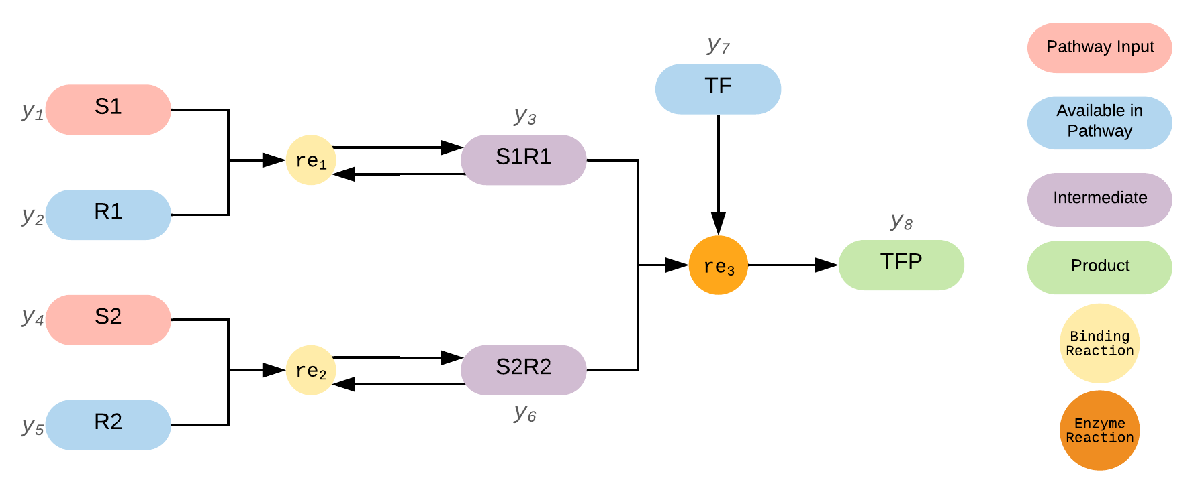

- **The OR pathway is defined in the **`orpathway`** and **`orpathwaysimple`** files.**

- `orpathwaysimple` uses these parameters: $k_f=1;~V_{max}=1;~k_r=2;~k_m=2$

- This model has 8 different components.

- These equations were used to model reaction rates in the pathway:

- **re1: **$k_f[S1][R1] -k_r[S1R1]$

- **re2: **$k_f[S2][R2]-k_r[S2R2]$

- **re3:** $\frac{V_{max}[TF]([S1R1]+[S2R2])}{k_m + [TF]}$

## Run the Pathway

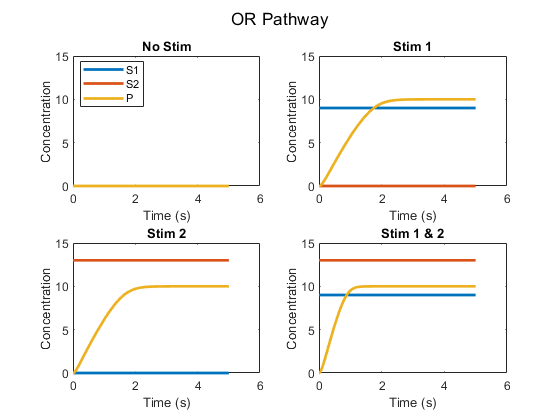

% Define initial conditions
Yi = zeros(8, 1);
% R1, R2, TF
Yi([2,5,7]) = 10;

% Generate stimulations for our four scenarios

% No stimulation
Yi([1, 4]) = [0, 0];
[T0, Y0] = ode23s(@orpathwaysimple, [0 5], Yi);

% Stimulation of Receptor 1 Only
Yi([1, 4]) = [9, 0];
[Ta, Ya] = ode23s(@orpathwaysimple, [0 5], Yi);

% Stimulation of Receptor 2 Only
Yi([1, 4]) = [0, 13];
[Tb, Yb] = ode23s(@orpathwaysimple, [0 5], Yi);

% Stimulation of both receptors
Yi([1, 4]) = [9, 13];
[Tab, Yab] = ode23s(@orpathwaysimple, [0 5], Yi);

% Plot the values for each scenario (T vs. Y)
figure;
sgtitle('OR Pathway') % Title for all subplots

subplot(2,2,1), plot(T0, Y0(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('No Stim');
legend({'S1', 'S2', 'P'}, 'Position', [.15 .75 .1 .1]);

subplot(2,2,2), plot(Ta, Ya(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 1');

subplot(2,2,3), plot(Tb, Yb(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 2');

subplot(2,2,4), plot(Tab, Yab(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 1 & 2');

**Figure Cation: **The designed pathway follows the correct stimulation pattern. Upper left: No stimulation results in no signal (product). Upper-right & Lower-left: Stiumulating with a single input results in an output signal. Lower-right: Stimulation with both inputs results in an output.

**Figure Conculsion: **When compared to the AND pathway, we only see differences in stimulation with only one input. When neither input is stimulated, or both inputs stimulated, the results are the same as in the AND pathway. When only one input is stimulated, we see an output signal, unlike in the AND pathway

## **Plot Product Concentration Against Time**

Response above 8 units detected at 2.1599 seconds.


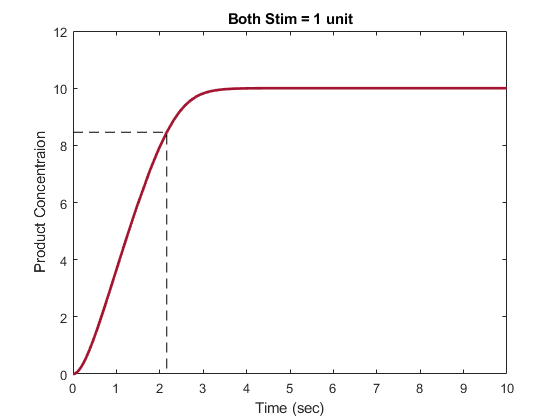

figure;
% Get the response time of a single simulation with both receports
% stimulated
Yi([1, 4]) = [1, 1];
[T, Y] = ode23s(@orpathwaysimple, [0 10], Yi);

% Plot Product Concentration against Time
prodConc(T, Y(:, 8))

**Figure Caption: **This figure shows the product concentration, [TFP] as the simulation progresses (maroon line). It is overlayed by dashed lines idicating the first time-point where [TFP] > 8 units.

**Figure Conclusion: **The system is not fast enough to satisfy our design requirement - it produces 8 units at 2.15 seconds with unit inputs.

## **Check Detection Time Threshold (**`studyresponsetime`**)**

The `studyresponsetime_orpathway` function is in the corresponding file.

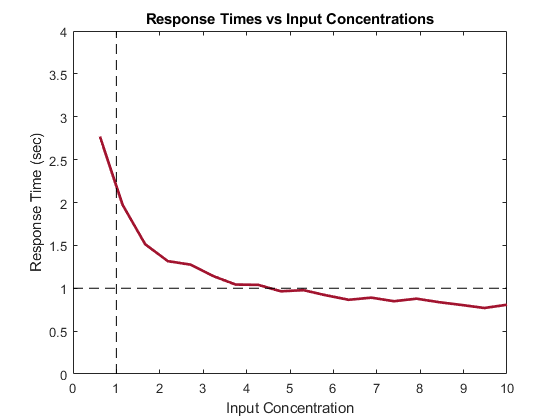

studyresponsetime_orpathway(@orpathwaysimple);
title('Response Times vs Input Concentrations');

**Figure Caption: **The figure shows the response times of our model pathway corresponding to various input concentrations, [S1] and [S2].  The plot is overlayed by dashed black lines that mark our design requirement (unit input concentration, and a response time < 1 second).

**Figure Conclusion: **This system does not satisfy our design requirement - 1 unit of input with a response time of 1 second to reach 8 units of product. This system only manages to produce the necessary amount of product in 1 second when the input concentrations are above 5 units.

## **Make the Reaction Faster to Achieve the Required Response Time**

Create a `modifiedorpathway` by writing a universal orpathway to increase vmax from 2 to 4.

The `orpathway` function is in the corresponding file.

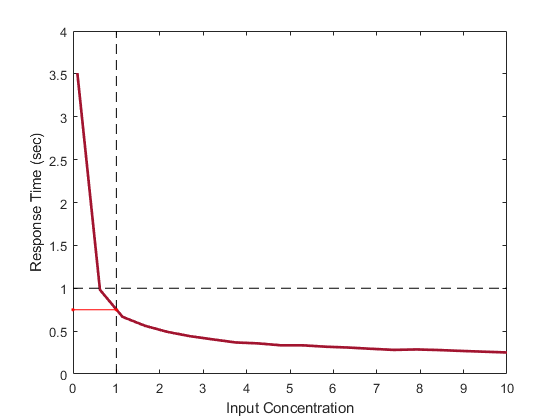

% Increase Vmax from 1 to 4
modifiedPathway = @(t,y) orpathway(t, y, 'kf', 1, 'Vmax', 4);
studyresponsetime_orpathway(modifiedPathway)
hold on, plot([0 1], [0.75, 0.75], 'r.-'), hold off;

**Figure Caption: **The figure shows the response times of our model pathway corresponding to various input concentrations, [S1] and [S2].  The plot is overlayed by dashed black lines that mark our design requirement (unit input concentration, and a response time < 1 second).

**Figure Conclusion: **Changing Vmax from 1 to 4 results in the model satisfying the design requirement - 1 unit input produced 8 units of product within 1 second. This is because increasing the reaction rate for a saturated enzyme results in faster conversion of substrate to products. The actual response time in this case is approximately $0.75\text{ s}$.

# `XOR` Pathway

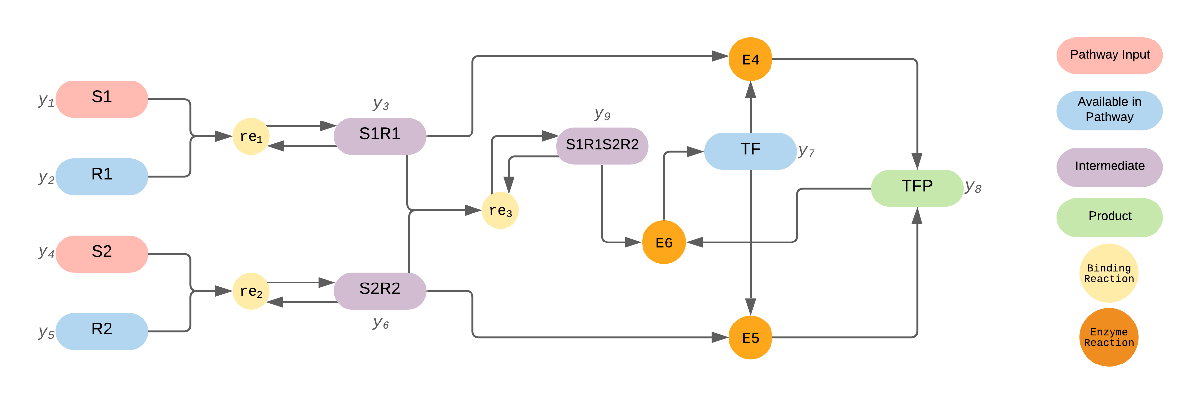

- **The XOR pathway is defined in the **`xorpathway`** and **`xorpathwaysimple`** files.**

- `xorpathwaysimple` uses these parameters: $k_f=50;~V_{max}=4;~k_r=2;~k_m=2$

- This model has 9 different components.

- These equations were used to model reaction rates in the pathway:

- **re1: **$k_f[S1][R1] -k_r[S1R1]$

- **re2: **$k_f[S2][R2]-k_r[S2R2]$

- **re3:** $\frac{V_{max}[TF]([S1R1]+[S2R2])}{k_m + [TF]}$

- **E4: **$\frac{V_{max}[TF][S1R1]}{k_m+[TF]}$

- **E5: **$\frac{V_{max}[TF][S2R2]}{k_m+[TF]}$

- **E6: **$\frac{V_{max}[TFP][S1R1S2R2]}{k_m+[TFP]}$

## Run the Pathway

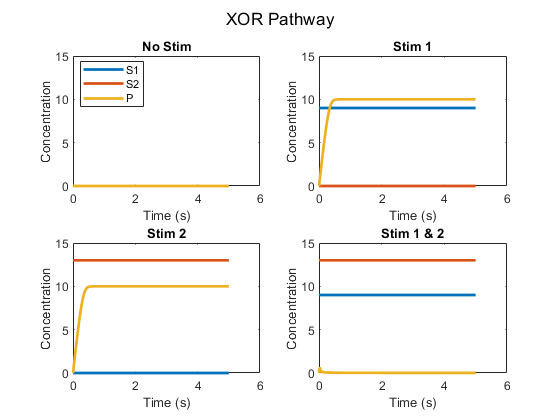

% Define initial conditions
Yi = zeros(9, 1);
% R1, R2, TF
Yi([2,5,7]) = 10;

% Generate stimulations for our four scenarios

% No stim
Yi([1, 4]) = [0, 0];
[T0, Y0] = ode23s(@xorpathwaysimple, [0 5], Yi);

% Stimulation of Receptor 1 Only
Yi([1, 4]) = [9, 0];
[Ta, Ya] = ode23s(@xorpathwaysimple, [0 5], Yi);

% Stimulation of Receptor 2 Only
Yi([1, 4]) = [0, 13];
[Tb, Yb] = ode23s(@xorpathwaysimple, [0 5], Yi);

% Stimulation of both receptors
Yi([1, 4]) = [9, 13];
[Tab, Yab] = ode23s(@xorpathwaysimple, [0 5], Yi);

% Plot the values for each scenario (T vs. Y)
figure;
sgtitle('XOR Pathway') % Title for all subplots

subplot(2,2,1), plot(T0, Y0(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('No Stim');
legend({'S1', 'S2', 'P'}, 'Position', [.15 .75 .1 .1]);

subplot(2,2,2), plot(Ta, Ya(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 1');

subplot(2,2,3), plot(Tb, Yb(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 2');

subplot(2,2,4), plot(Tab, Yab(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 1 & 2');

**Figure Cation: **The designed pathway follows the correct stimulation pattern. Upper left: No stimulation results in no signal (product). Upper-right & Lower-left: Stiumulating with a single input results in an output signal. Lower-right: Stimulation with both inputs results in no output.

**Figure Conculsion: **When compared with the AND and OR pathways, the behavior with no stimulation is the same. When only one receptor is stimulated, the OR and XOR pathways produce outputs, but the AND pathway does not. When both receptors are stimulted the AND and OR pathways produce outputs, but the XOR pathway does not.

### **Now using  kf = 8;  Vmax = 4; kr = 2; km = 2; rerun and replot the above pathway. what happens? is the new  xorpathyway better or worse ? why? **

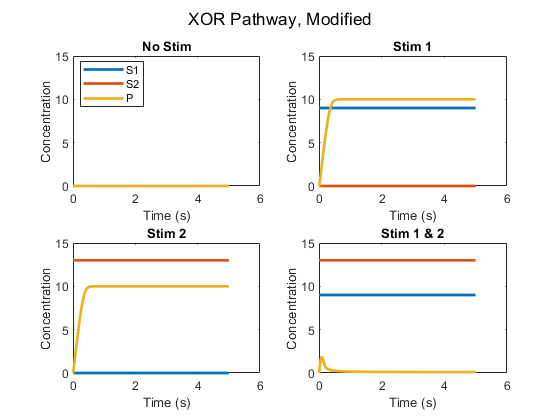

% Define initial conditions
Yi = zeros(9, 1);
% R1, R2, TF
Yi([2,5,7]) = 10;

% Change parameters
modifiedPathway = @(t,y) xorpathway(t, y, 'kf', 8, 'Vmax', 4', 'km', 2, 'kr', 2);

% Generate stimulations for our four scenarios

% No stim
Yi([1, 4]) = [0, 0];
[T0, Y0] = ode23s(modifiedPathway, [0 5], Yi);

% Stimulation of Receptor 1 Only
Yi([1, 4]) = [9, 0];
[Ta, Ya] = ode23s(modifiedPathway, [0 5], Yi);

% Stimulation of Receptor 2 Only
Yi([1, 4]) = [0, 13];
[Tb, Yb] = ode23s(modifiedPathway, [0 5], Yi);

% Stimulation of both receptors
Yi([1, 4]) = [9, 13];
[Tab, Yab] = ode23s(modifiedPathway, [0 5], Yi);

% Plot the values for each scenario (T vs. Y)
figure;
sgtitle('XOR Pathway, Modified') % Title for all subplots

subplot(2,2,1), plot(T0, Y0(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('No Stim');
legend({'S1', 'S2', 'P'}, 'Position', [.15 .75 .1 .1]);

subplot(2,2,2), plot(Ta, Ya(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 1');

subplot(2,2,3), plot(Tb, Yb(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 2');

subplot(2,2,4), plot(Tab, Yab(:, [1,4,8]), 'LineWidth', 2), ylim([0 15]); 
xlabel('Time (s)'), ylabel('Concentration'), title('Stim 1 & 2');

**Figure Cation: **The designed pathway follows the correct stimulation pattern. Upper left: No stimulation results in no signal (product). Upper-right & Lower-left: Stiumulating with a single input results in an output signal. Lower-right: Stimulation with both inputs results in no output.

**Figure Conculsion: **When Vmax is reduced from 50 to 4, we still see that as time progresses, there is no product. However, the modified pathway exhibits worse overall performance. Within the first second, we see a larger spike in product concentration than we did for the larger Vmax value. This is because, with a higher Vmax, the product (TFP) is consumed faster in the E6 reaction than with a smaller Vmax - since Vmax determines how fast a saturated enzyme converts substrate to product. Thus, with a lower Vmax, more TFP is allowed to form before the E6 reaction is saturated.

## **Check Detection Time Threshold with **`xorpathway`

The `studyresponsetime_xorpathway` function is in the corresponding file.

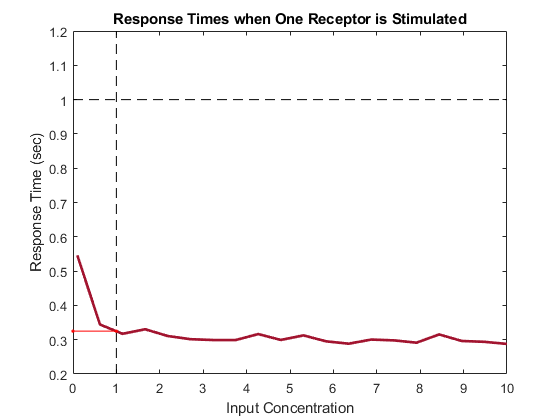

% Since there is no product when both receptors are stimulated, we will
% look at the response times when only one receptor is stimulated.
% Since the rates for re1 and re2 will be numerically equivalent, it should
% not matter which receptor we chose to stimulate.
% Thus, this figure shows response times when R1 is stimulated.
studyresponsetime_xorpathway(@xorpathway);
title('Response Times when One Receptor is Stimulated');
hold on, plot([0 1], [0.325, 0.325], 'r.-'), hold off;

**Figure Caption: **The figure shows the response times of our model pathway corresponding to various input concentrations, [S1] and [S2].  The plot is overlayed by dashed black lines that mark our design requirement (unit input concentration, and a response time < 1 second).

**Figure Conclusion:** This model does satisfy the design requirement. With 1 unit input, it produces 8 units of the product in less than 1 second. The exact  response time for 1 unit input is 0.325 seconds (325 miliseconds).

function prodConc(T, Y)
% This function generates a plot of product concentration against time
% using the results from ode23s.
% It also determines if the modelled pathway satisfies our design
% requirement ([P] >= 8 in 1 second)
  figure;
	plot(T, Y, 'Color', '#A2142F', 'LineWidth', 2), title('Both Stim = 1 unit');
	xlabel('Time (sec)'), ylabel('Product Concentraion');
	
	% Find the first time poitn where [P] >= 8 (design requirement)
	pos = find(Y >= 8, 1, 'first');
	if isempty(pos)
		fprintf('No response detected above 8 units.\n')
	else
		rtime = T(pos); % Find response time
		fprintf('Response above 8 units detected at %.4f seconds.\n', rtime);
		hold on; % Overlay position on figure
		plot([0 rtime rtime], [Y(pos) Y(pos), 0], 'k--');
		hold off;
	end
end